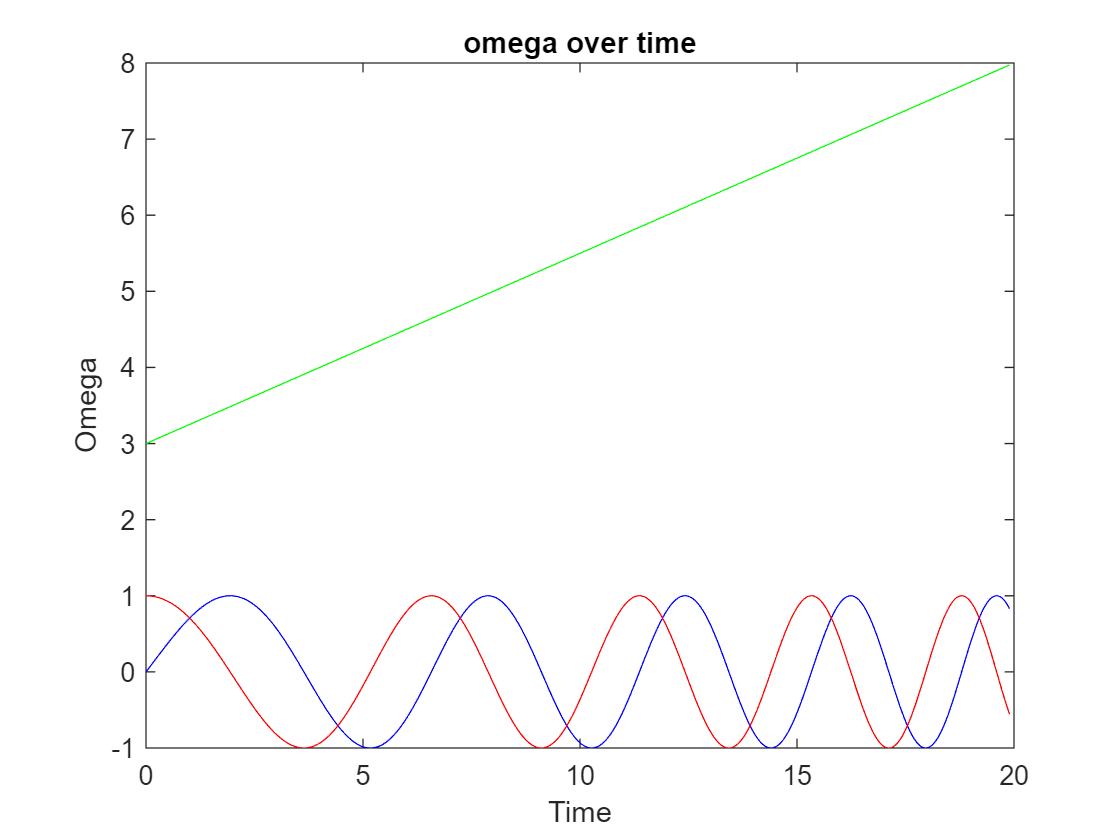

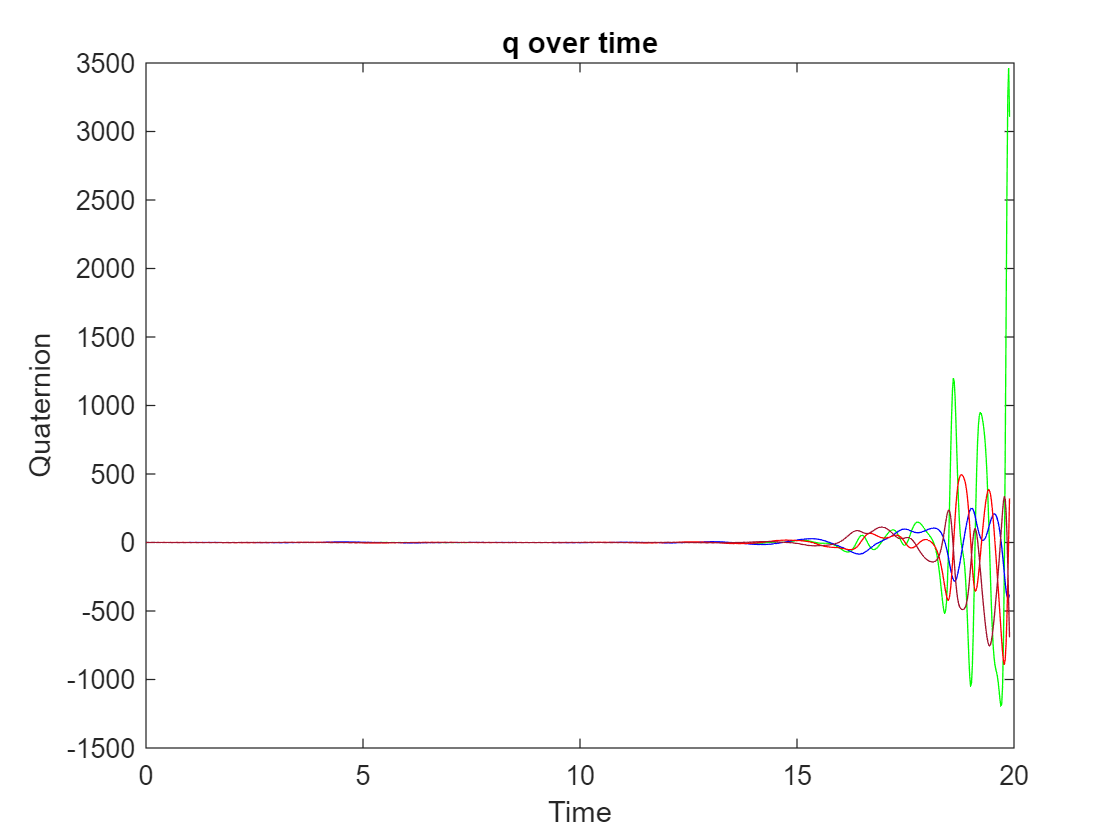

% Euler EOMs

clear; clc;

% Initial conditions
eDCMb = [0 0 1; 1 0 0; 0 1 0];
W0 = [3 0 1];
Q0 = DCM_to_Quaternion(eDCMb);
y0 = [W0 Q0'];

% ODE45 setup variables and functions
T = 9.5*2*pi/W0(1);
tspan = linspace(0,T,1000);
tol = 1e-13;

options = odeset('RelTol', tol, 'AbsTol', tol);

% ODE45 call - Kinematic
[t,x_k] = ode45(@diffEqKinematic,tspan,y0,options);

% plot2d(t_k,x);

% ODE45 call - Dynamic
[t,x_d] = ode45(@diffEqDynamic,tspan,y0,options);

plot2d(t,x_k,x_d);